clear all
clc
close all

[xx1,xx2,tt] = IVP(4.66,0.0917,0.0765,100,50,10,1000);

x1 =   100.0000   70.2490   50.5709   37.2190   27.9214   21.2829   16.4326   12.8166   10.0744    7.9657    6.3264    5.0409    4.0264    3.2217    2.5812    2.0700    1.6612    1.3338    1.0713    0.8607    0.6916    0.5559    0.4468    0.3591    0.2887    0.2321    0.1866    0.1500    0.1206    0.0969    0.0779    0.0627    0.0504    0.0405    0.0326    0.0262    0.0210    0.0169    0.0136    0.0109    0.0088    0.0071    0.0057    0.0046    0.0037    0.0030    0.0024    0.0019    0.0015    0.0012


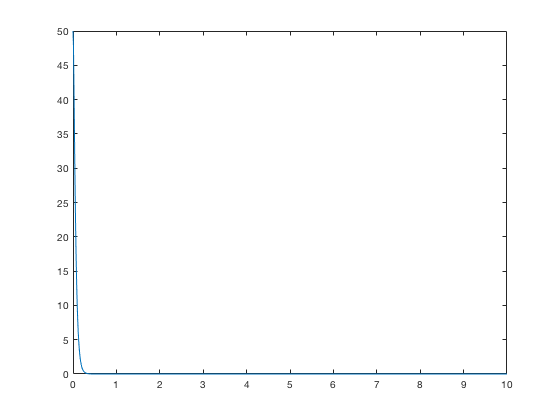

plot(tt,xx2);

function [x1,x2,t] = IVP(k,m1,m2,x1_0,x2_0,T,N)
A = [1 0 0 0
    0 1 0 0
    0 0 -2*k/m1 k/m1
    0 0 k/m2 -k/m2];
dt = T/N;
t = linspace(0,T,N);

SOL = NaN(4,length(t));
SOL(3,1) = x1_0;
SOL(4,1) = x2_0;
SOL(1,1) = 500000000;
SOL(2,1) = 1298163916938619836198269186;

for (k = 2:length(t))
s = A*SOL(:,k-1)+A*(SOL(:,k-1)+dt*A*SOL(:,k-1));
SOL(:,k) = SOL(:,k-1) + 0.5*dt*s;
end

x1 = SOL(3,:)
x2 = SOL(4,:);

end